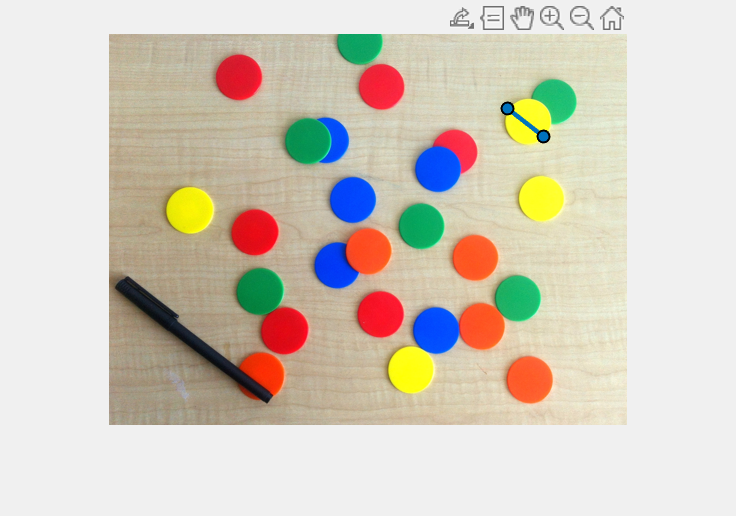

rgb = imread('coloredChips.png');
imshow(rgb)
d = drawline;

`Lets you import image and draw a line on image`

pos = d.Position;
diffPos = diff(pos);
diameter = hypot(diffPos(1),diffPos(2));

`Analyses the line made, finds its position.`

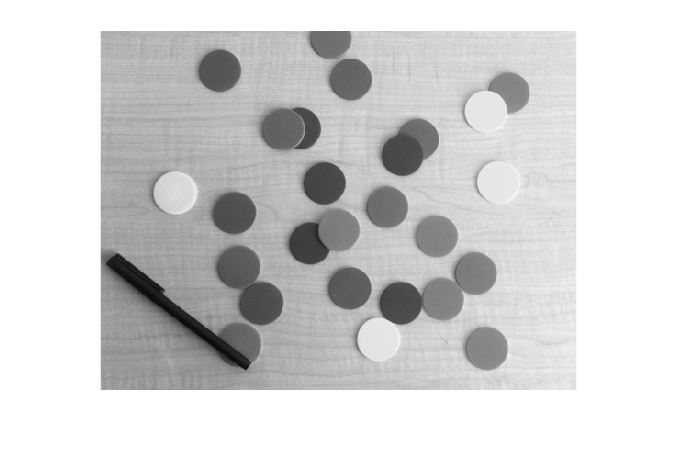

grey_image = rgb2gray(rgb);
imshow(gray_image)

[dark_centers,dark_radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','dark','Sensitivity',0.95)

dark_centers =   146.6065  198.7207
  328.7131  135.5812
  130.6918   43.5773
  176.2573  297.1950
  312.2446  192.3270
  327.0974  297.2876
  244.0222  166.5049
  271.6521  280.7950
  366.6151  224.0908
  273.0380   53.2096


dark_radii =    22.7071
   22.5710
   22.7744
   23.5064
   22.9551
   22.9995
   22.8975
   23.0298
   22.4011
   22.6906


[centers,radii] = imfindcircles(rgb,[20 25],'ObjectPolarity','bright','Sensitivity',0.93)

centers =   420.5377   88.1068
   81.8206  176.8402
  303.4888  336.2105
  201.0044  107.8387
  433.4997  164.8196


radii =    22.8563
   23.4437
   22.6400
   22.5504
   22.0999


`Here, rgb2gray turns original image into a grey scale image.`

`imfindcircles(decired image, range of circle radius, )`

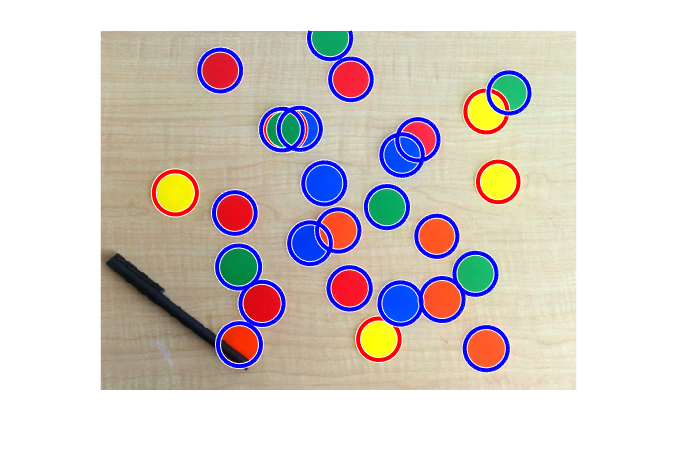

dark_h =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


imshow(rgb)
h = viscircles(centers,radii);
dark_h = viscircles(dark_centers,dark_radii, 'Color','b')